## Class Structure Checks Livescript

### Check Rocket Naming and Rocket Class

% Should create a rocket object and display its properties
r = Rocket

r =   Rocket with properties:

            name: "CMS"
         refArea: 0.0222
          thrust: 4.2703e+03
        exitArea: 0.0071
    exitPressure: 7.5842e+04
          radius: 0.0841
          length: 5.1237



% Should show the name "CMS"
r.name

ans = "CMS"


% Should show the length of the rocket
r.length

ans = 5.1237


% Should show the documentation for the rocket class
help Rocket

 Rocket: The rocket class is the class the governs all the
  properties of the rocket itself. If no inputs are given, the
  values default to values for CMS.
 
  INPUTS:
  name = the name of the rocket system
  refArea = reference area for aerodynamics [m^2]
  thrust = nominal sea level thrust [N]
  exitArea = exit area of nozzle [m^2]
  exitPressure = exit pressure [Pa]
  radius = radius of rocket [m]
  length = total length of rocket [m]
 
  OUTPUTS:

    Documentation for Rocket




% Create an entirely new rocket with new parameters:
r2 = Rocket;
r2 = CreateRocket(r2,"TestRocket",1,1e6,0.5,1e5,.25,50)

r2 =   Rocket with properties:

            name: "TestRocket"
         refArea: 1
          thrust: 1000000
        exitArea: 0.5000
    exitPressure: 100000
          radius: 0.2500
          length: 50


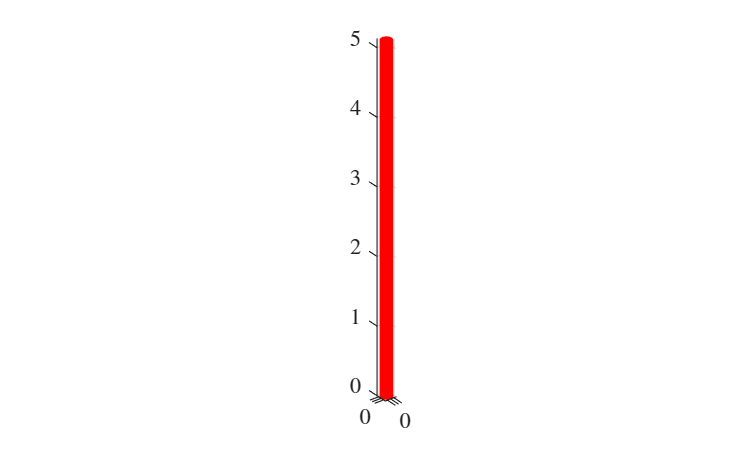


% Draw the rocket:

drawRocket(r)

### Check Environment Setup

env = Environment

env =   Environment with properties:

                Date: 31-May-2025
           Elevation: 627.9100
             LatLong: [35.3474 -117.8091]
    geocentricRadius: 6.3711e+06



% get the date from the environment. Should default to current date.
env.Date

ans = datetime
   31-May-2025


% get the location information for the launch site:
loc = env.LatLong

loc =    35.3474 -117.8091



% get the height of the launch site (should be 627.91 m):

alt = getElevation(env)

alt = 627.9042


% change the launch site to Kennedy Space Center Pad 39A:

env2 = setLaunchSite(env, 28.608298864609225, -80.60413021610083)

env2 =   Environment with properties:

                Date: 31-May-2025
           Elevation: 8.1625
             LatLong: [28.6083 -80.6041]
    geocentricRadius: 6.3711e+06



% keep the same launch site and change date to July 16,1969:

date = datetime("July 16, 1969")

date = datetime
   16-Jul-1969



env2 = setLaunchSite(env, 28.608298864609225, -80.60413021610083, date)

env2 =   Environment with properties:

                Date: 16-Jul-1969
           Elevation: 627.9100
             LatLong: [35.3474 -117.8091]
    geocentricRadius: 6.3711e+06


### Check Simulation settings

sim = Simulation('burnout',0.1,"high",1)

sim =   Simulation with properties:

    EndCondition: "burnout"
          Output: 1
        Timestep: 0.1000
        Fidelity: "high"
          relTol: 1.0000e-04
          absTol: 1.0000e-07


### Check the Sensor Settings

% Create an altimeter. The altimeter should have a variance of 16 m^2
altimeter = Altimeter("Altimeter", 0.25, 16,.5, 0)

altimeter =   Altimeter with properties:

            Name: "Altimeter"
    SamplingRate: 0.2500
        Variance: 16
      Resolution: 0.5000
            Bias: 0


% Create a GPS. The GPS should be more accurate. Define a different
% variance for each of the axes (pos xy, pos z, vel)
GnssVariance = [2.56,9, 0.01]

GnssVariance =     2.5600    9.0000    0.0100


gnss = GNSS("GNSS",1,GnssVariance,.1,0)

gnss =   GNSS with properties:

            Name: "GNSS"
    SamplingRate: 1
        Variance: [2.5600 9 0.0100]
      Resolution: 0.1000
            Bias: 0




% get a single altimeter measurement
AltitudeMeasurement(altimeter, 100, 0)

ans = 101.0456


% get altimeter measurements for a timespan
h = 0:5:50;
t = 0:.1:1;

heightEst = AltitudeMeasurement(altimeter,h,.1)

heightEst =    -0.6494       NaN       NaN   12.8720       NaN   21.4971       NaN       NaN   37.1520       NaN   49.2310


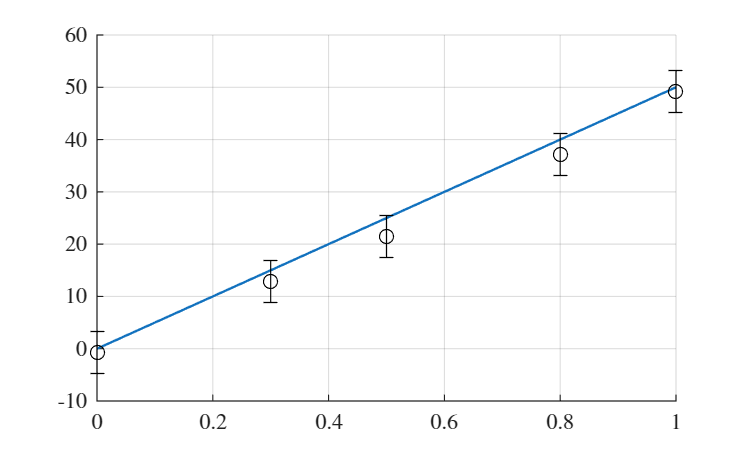


%heightEstGPS = GNSSMeasurement(gnss,)

close all

hold on
plot(t,h)
errorbar(t,heightEst,sqrt(altimeter.Variance), 'ko')

hold off

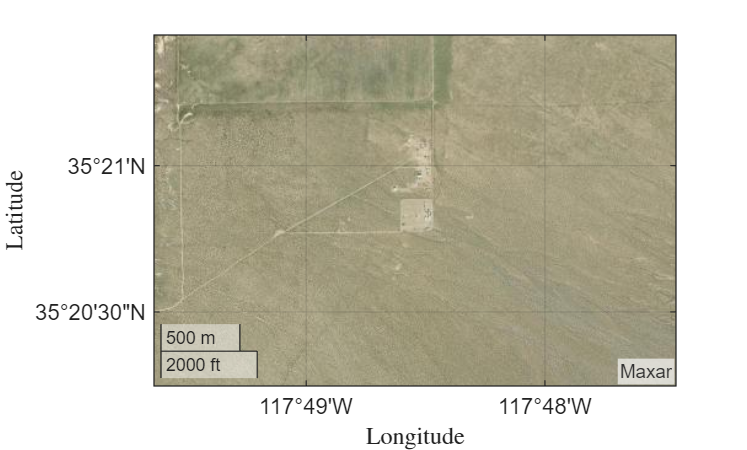

% create a 2D plot of the launch site
geoplot(env.LatLong(1),env.LatLong(2))
geolimits([env.LatLong(1)-.01,env.LatLong(1)+0.01],[env.LatLong(2)-.01,env.LatLong(2)+.01])


geobasemap satellite


% create a 3D plot of the launch site with a dot at the launch. Move it
% around with the mouse!
uif = uifigure;
g = geoglobe(uif);

geoplot3(g, env.LatLong(1), env.LatLong(2), env.Elevation, 'mo', MarkerSize= 5)
%campitch(g,-30)
%camheading(g,45)
